# 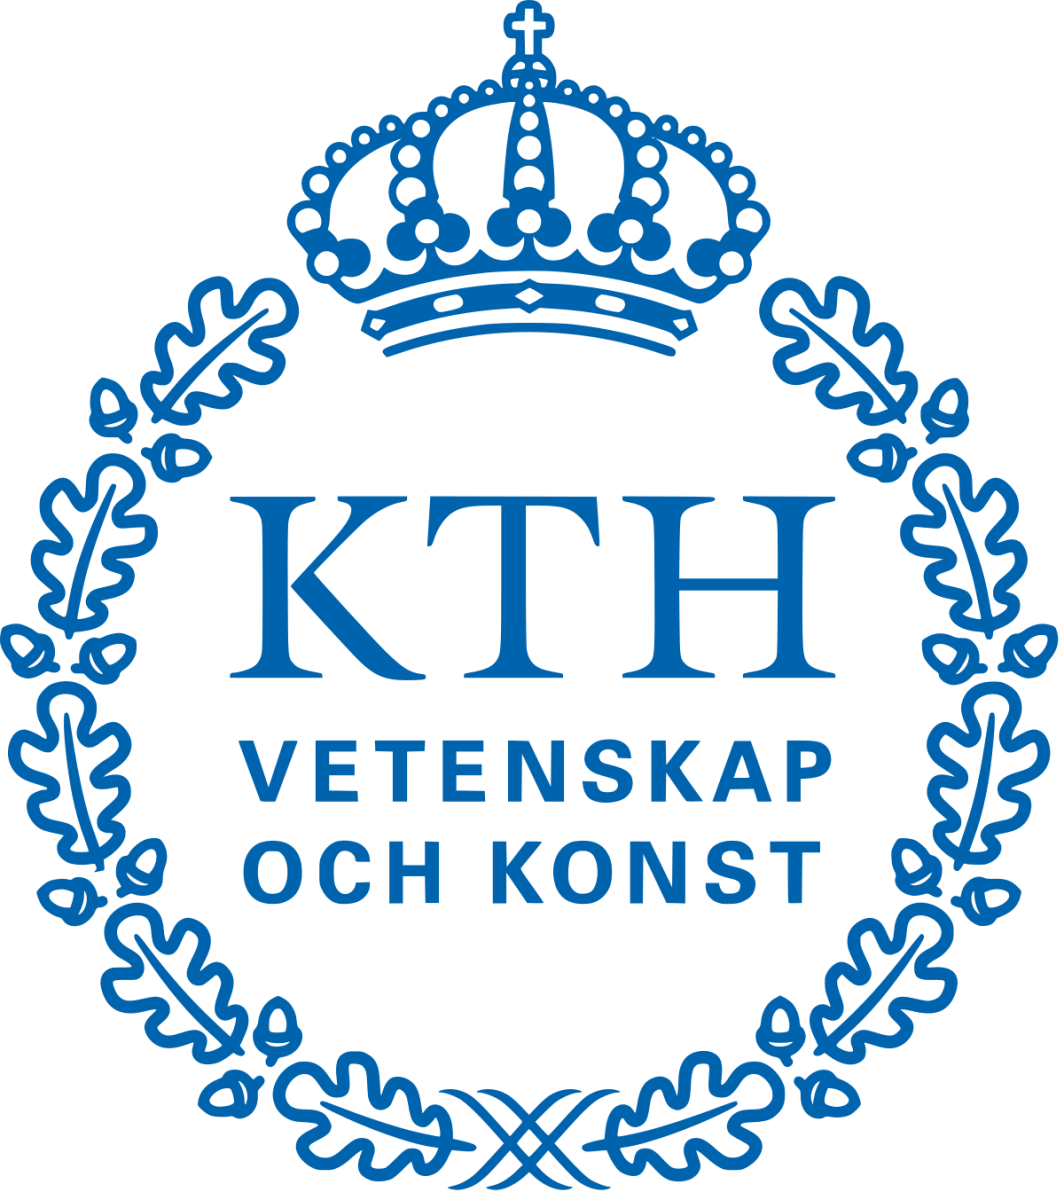

# SD2125 Signals and Mechanical Systems

# HOME ASSIGNMENT 2 (HA2)

# STUDENT 1 Marcus von Post Carlsson

# STUDENT 2 Spencer Karlström Huerta

In these exercises you are intended to learn some basic concepts in signal analysis and how to use these functions in MATLAB with. The assignment is divided into four main sections: (1) Fourier series, (2) sampling, (3) aliasing, and (4) spectrograms. The assignment is intended to be in pairs, but it is also fine to do it alone (in that case, please remove the STUDENT 2 line). 

The product help under the help menu in MATLAB is recommended to use when understanding what predefined functions are suitable to implement. Pay special attention to how MATLAB outputs are organized. It is recommended to "Run Section" instead of "Run" (the whole code) to prevent unnecessary code runs.  

# INSTRUCTIONS FOR ASSIGNMENT AND REPORT

In this Live Script, you will find **empty CODE slots **where you must fill in relevant codes and **empty ANSWER slots **where you must fill in answers to given questions. The structure of the Live Script should not be modified, that is, **do not change/remove headings, numberings, or sections—even if you submit blank in any of them**. Make sure you also add your name(s) at the top of this document (here). If you did the assignment alone, add your name in Student 1 and delete the row for Student 2. 

Once you are finished with your assignment, you should produce a PDF report out of the Live Script. No introduction, discussion nor conclusion are required in the report, only answer the questions and show the plots as instructed. You can produce the PDF report by clicking `"Save As..."` and selecting **PDF (*.pdf)** format. 

**OBS**: **Make sure you save the PDF file including the name(s) of the student(s) who did the work: HA2_Initial-Surname_Initial-Surname, for example: "**`HA2_K-Bolin_E-Zea.pdf`**".  **

# 1: FOURIER ANALYSIS

## 1.1 Fourier series

Discuss with your colleague the basic concept of Fourier series and what kind of signals they are suitable to map.

### 1.1.1.     Fourier series of a harmonic signal

Calculate the Fourier series for the signal `sin_4_harmonic `below using the command `“fit”`. The Fourier series coefficients should be varied between `N = 1, 2, 4 & 8 `see example below. Examine the coefficients in `cN` and the root mean squared error (rmse) in `gN`. Plot the results and compare to the original signal. 

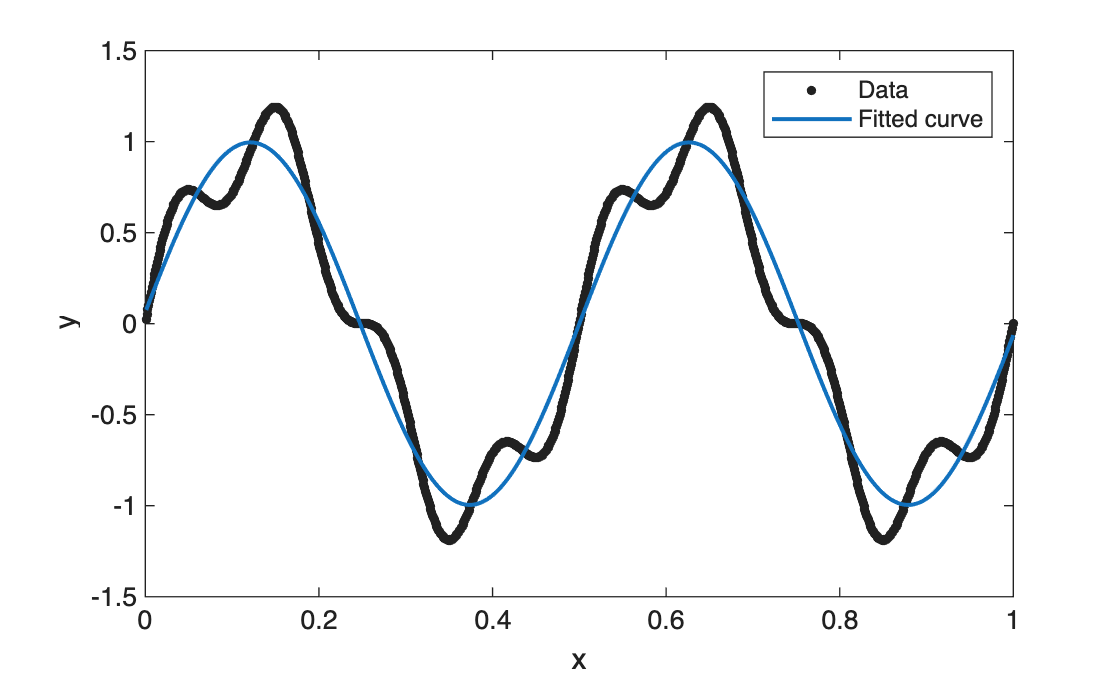

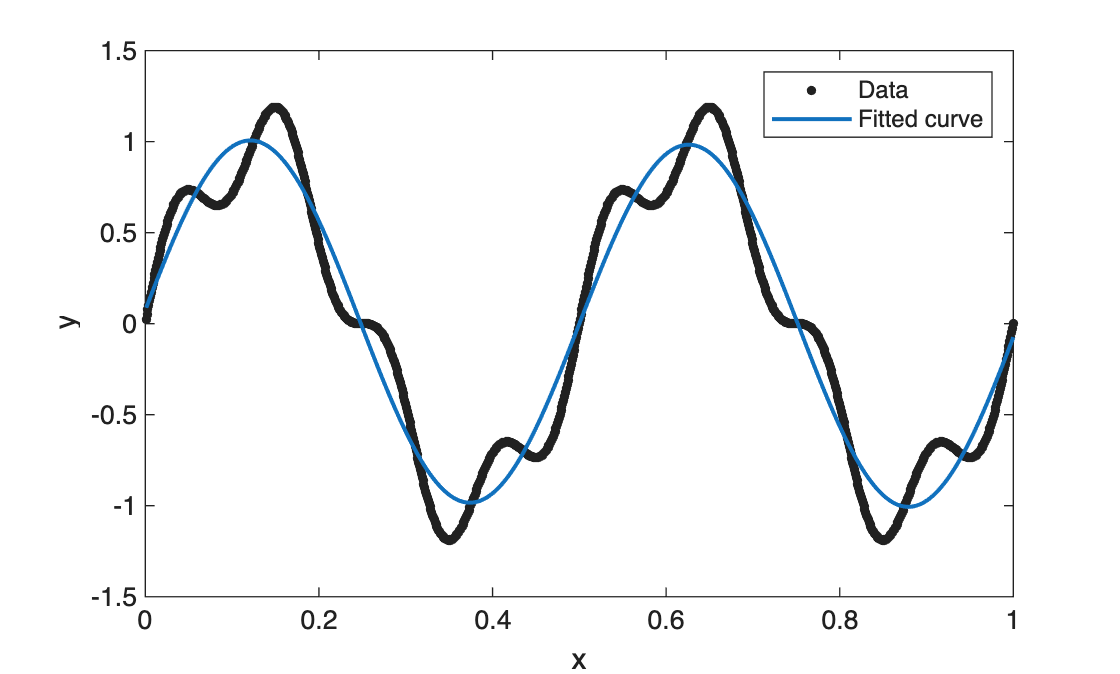

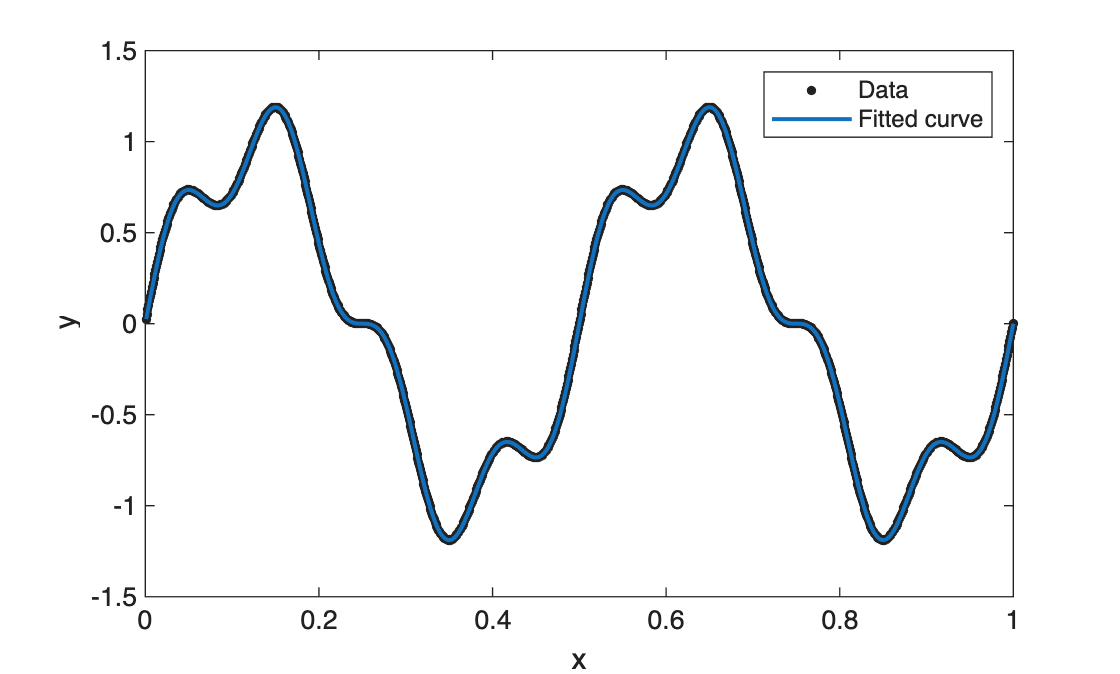

% add your code here
T = (0.001:0.001:1)';
Nns = [1,2,4,8];

cN = cell(1, length(Nns));
gN = cell(1, length(Nns));

for i = 1:length(Nns)
    modelName = sprintf('fourier%d', Nns(i)); %bättre än att skriva ut flera gånger

    [cN{i}, gN{i}] = fit(T, sin_N_harmonic, modelName);
    figure;
    plot(cN{i},T, sin_N_harmonic);

end

***ANSWER:  The coefficients are not precise enough on fourier1 and fourier2 but almost perfect on this time interval for fourier4 and fourier8***

### 1.1.2.     Fourier series of a sound signal

Calculate the Fourier series for one of the sound signals `S1-S4 `(same as used in **Task 1.2** of **Home Assignment 1**) using the command `“fit”` and Fourier series coefficients `N = 1, 2, 4 & 8 `see example below. Plot the results and compare to the original signal. 

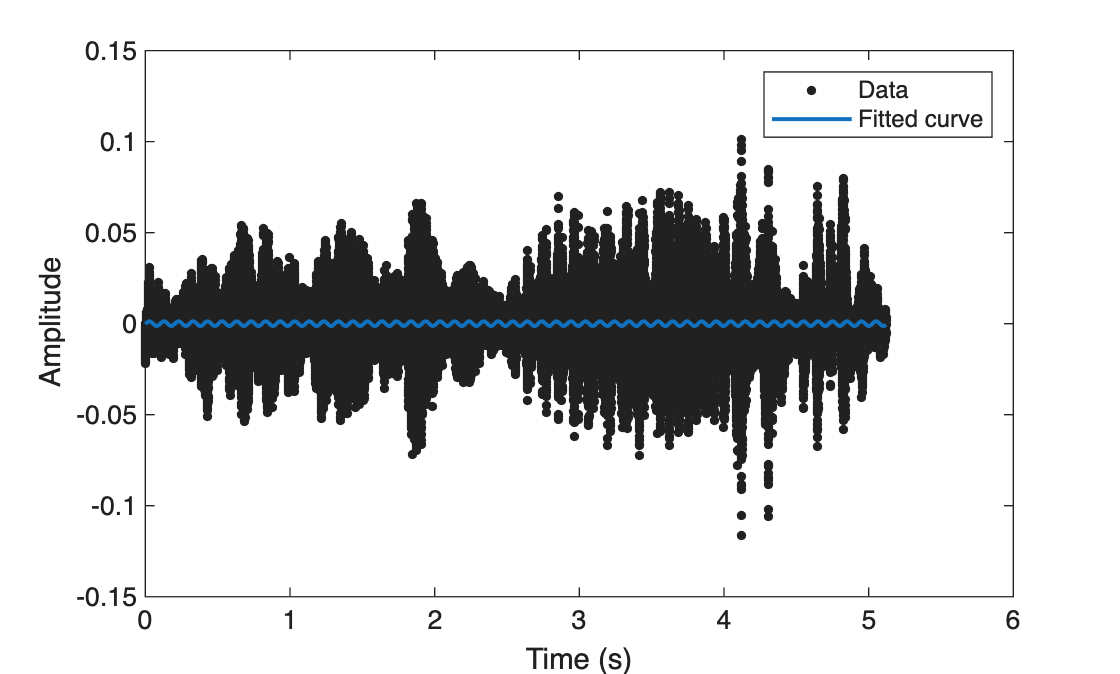

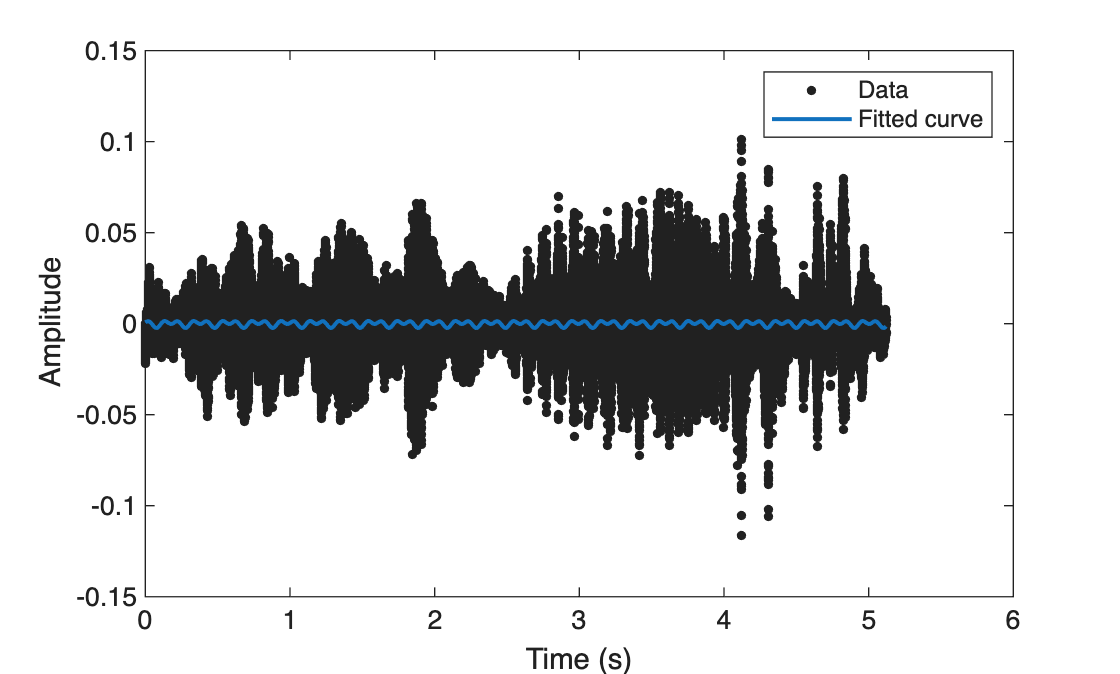

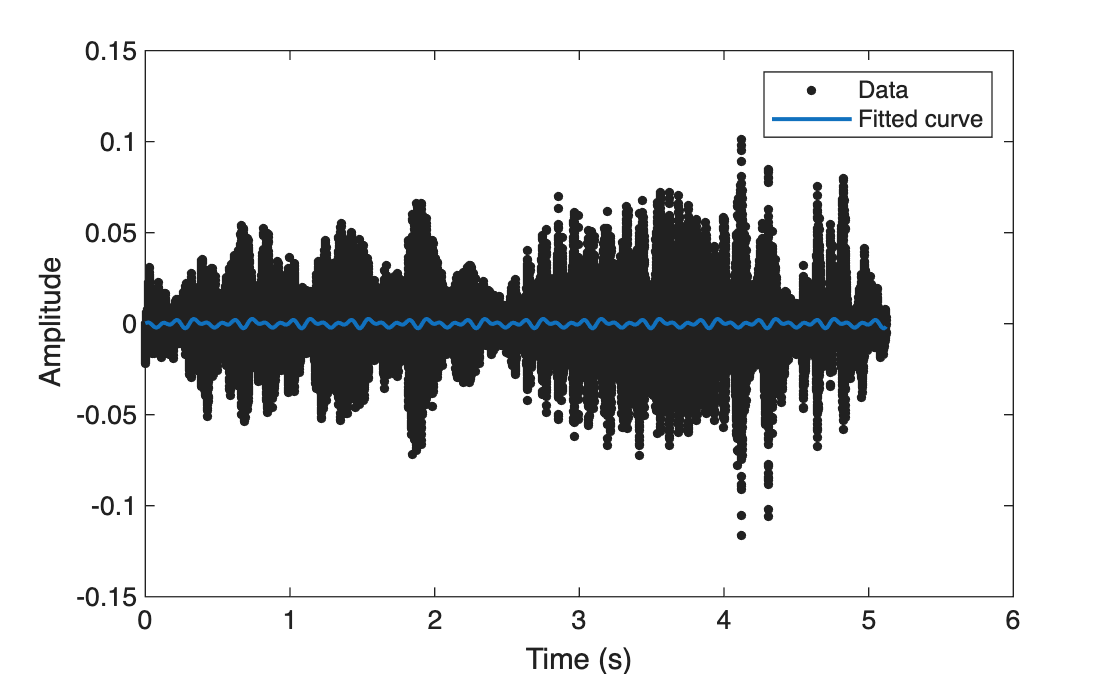

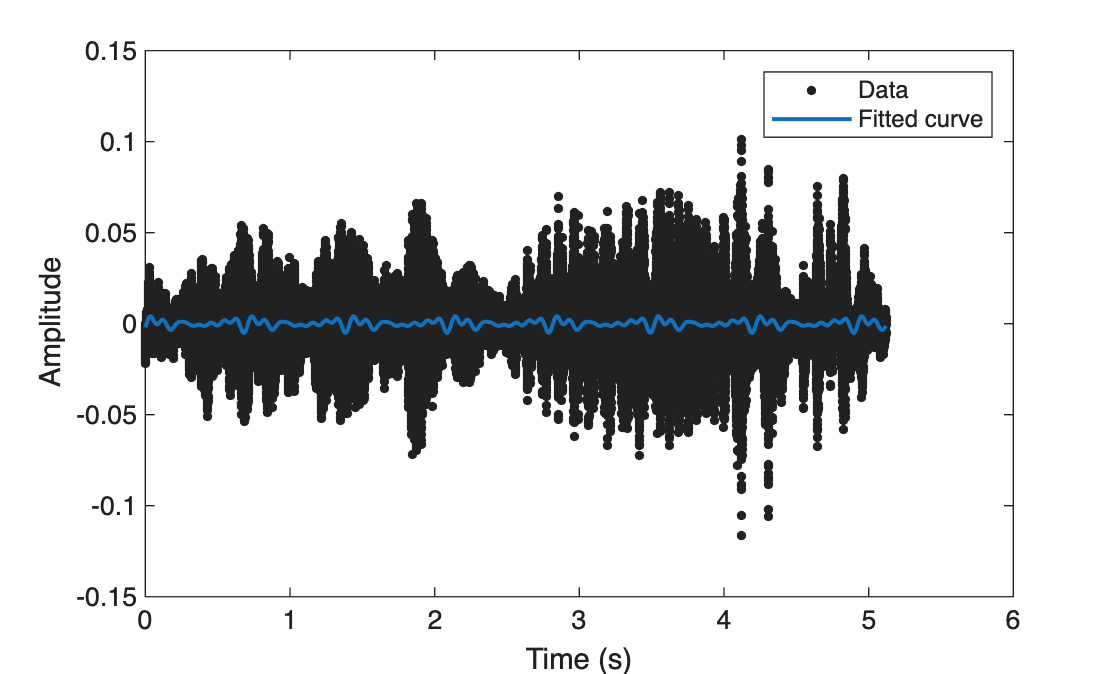

% add your code here
[SX, Fs ] = audioread("Sound1.wav");
Nns = [1,2,4,8];

time_SX = (0:length(SX)-1)'/Fs;
SX = mean(SX, 2);

cN_SX = cell(1, length(Nns));
gN_SX = cell(1, length(Nns));

for i = 1:length(Nns)
    modelName = sprintf('fourier%d', Nns(i)); %bättre än att skriva ut flera gånger

    [cN_SX{i}, gN_SX{i}] = fit(time_SX, SX, modelName);
    figure;
    plot(cN_SX{i},time_SX, SX);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

***ANSWER: For sound1 it cant do a fourier transform to make it match the data. ***

### 1.1.3.     Explain the differences in the results seen in Tasks 1.1.1. and 1.1.2. 

***ANSWER: The result in task 1.1.1 is much better since the data is periodic, but in 1.1.2 a nonperiodic signal sound was chosen and therefore the result was quite lousy.***

## 1.2 Fourier transform and inverse Fourier transform

Discuss with your colleague what kind of operation a Fourier transform is and what kind of output will be produced when a time series is Fourier transformed. Read carefully the MATLAB help on “`fft” `and then reread it one more time. 

Now, create a simple sinusiodal with an added phase that is the the average of your ages divided by 10. Use the code: 	

% add your code here
freq=10;                                 % frequency of stimuli (Hz)
fs = 1024;                               % Sample frequency (Hz)
t = 0:1/fs:1-1/fs;                       % 1 sec sample
A = sqrt(2);    
mean_age = 24 / 10;
x = A*sin(2*pi*freq*t+mean_age/10);      
m = length(x);                           % Window length
N = pow2(nextpow2(m));                   % Transform length 
y = fft(x,N);                            % DFT 
help fft

 fft - Fast Fourier transform

    Syntax
      Y = fft(X)
      Y = fft(X,n)
      Y = fft(X,n,dim)

    Input Arguments
      X - Input array
        vector | matrix | multidimensional array
      n - Transform length
        [] (default) | nonnegative integer scalar
      dim - Dimension to operate along
        positive integer scalar

    Output Arguments
      Y - Frequency domain representation
        vector | matrix | multidimensional array

    Examples
      

### 1.2.1.     Plot the time signal `x` with the correct x- and y-axis

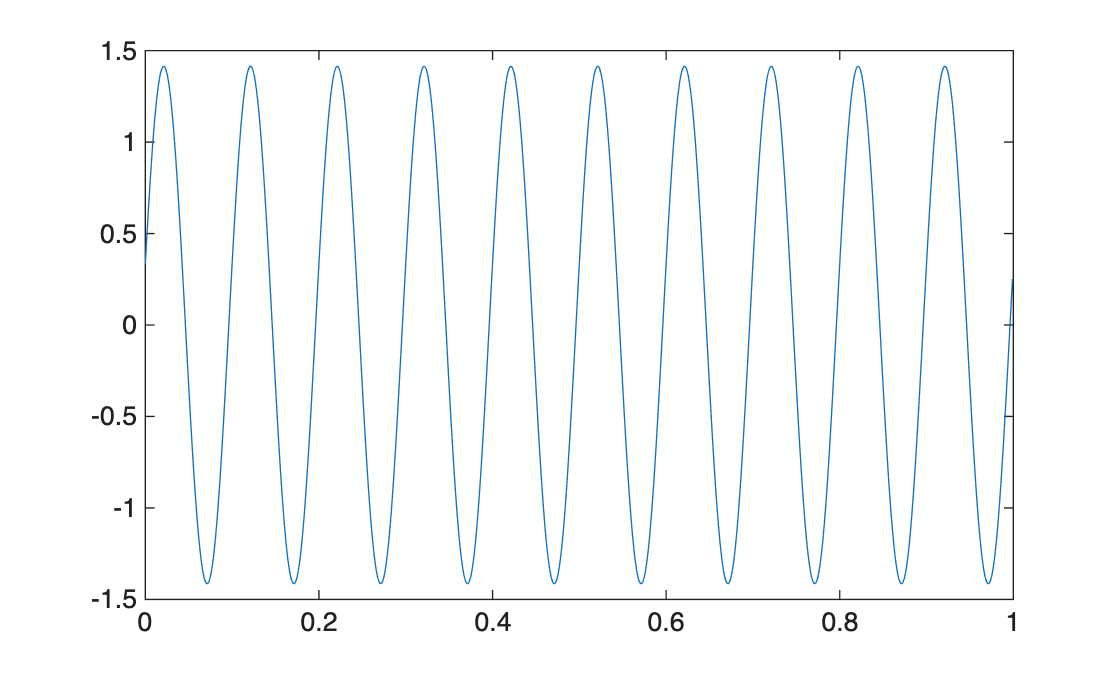

% add your plot here
plot(t, x)

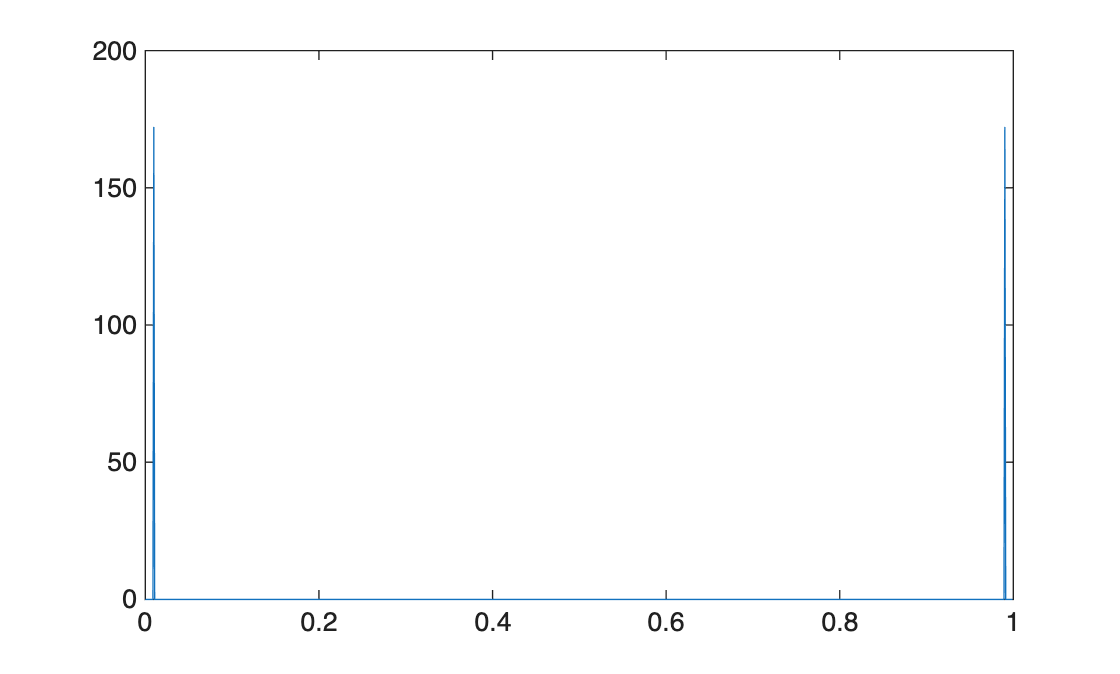

plot(t,y)

### 1.2.2.     Plot the raw and scaled output vector of the FFT magnitude spectrum

% add your plot here


The above corresponds to the raw amplitude spectrum of the signal. Proceed to scale the amplitude correctly in order to get a correct representation and plot it. 

% add your plot here


### 1.2.3.     Describe how the output vector `y` from `fft` is sorted

What frequency does the output vector's first element/index (`n = 1`) correspond to, and what does the last element (`n = NFFT`)? **Note that the **`MATLAB`** help can be unclear on this issue, so an additional check on the web is recommended.**

***ANSWER: ****< Add your answer here >*

### 1.2.4.     Verify the inverse FFT of a forward FFT

Use the inverse Fourier transform command `"ifft"` on the output from the `“fft”` results from the signal above

% add your code here


Is the result equal to the original time signal?

***ANSWER: ****< Add your answer here >*

### 1.2.5.     Read and FFT the file "*Classic.wav*" with the code you used in Task 1.2.2, set `n = 1024`

% add your code here


How large part of the original sound is used? What has been analyzed in the remaining signal? Comment on the consequences on bandwidth, computational time, and RAM usage if you were to determine the frequency content of a 4-minute song with a sampling frequency of 44100 Hz?

***ANSWERS: ****< Add your answers here >*

# 2: SAMPLING

Advice: When plotting discrete spectra, the command `“stem”` is better than `“plot”` to see the properties of the different frequencies. Therefore, use the former command when appropriate in the exercises below. OBS: **Tasks 2.1** & **2.2** here are similar to **Tasks 3.1.3** & **3.2.3** in Home Assignment 1, so copy and paste.

## 2.1.     Read the Sound4.wav 4 s sample using `“audioread”`

Plot the data in the time domain and listen to it using `“audioplayer”`. 

% add your code here


## 2.2.     Resample the signal at every 4th and 32nd points

Plot the resampled signals in the same graph as the original sample using “`resample`” in MATLAB. 

% add your code here


Describe the difference between the three curves by zooming in on a small time segment.

***ANSWER: ****< Add your answer here >*

## 2.3.     Plot one-sided spectra using 512 samples for all three sampling frequencies (Fs, Fs/4, Fs/32) and compute the frequency resolution (`∆f`) for all these spectra

% add your code here


Explain how the amplitudes differ for each sampled signal and explain why that is so.

***ANSWERS: ****< Add your answers here > *

## 2.4.     Listen to the downsampled signals and compare them to the original recording

Remember to change the sampling frequency in the `“audioplayer”` input.

% add your code here


Describe the differences.

***ANSWERS: ****< Add your answers here >*

# 3: ALIASES

Reuse the 10 Hz sinusoid from Task 1.2.

## 3.1.     Sample the sinusoid with 32 Hz, 20 Hz, 16 Hz, and 8 Hz

% add your code here


Comment on the resulting frequency plots. When can you observe aliasing?

***ANSWERS: ****< Add your answers here >*

# 4: SPECTROGRAM

In this assignment, you are investigating a recording of an aircraft (Airbus A320) flyover and will estimate the speed of the plane from this recording “A320”. Start by listening to the recording. You should be able to hear a clear tonal sound during the recording, along with an eventually decreasing pitch (frequency of the tone). The sound source is caused by cavities for fuel over pressure disposure situated under the wings and is known in aeroacoustics as a Helmholtz resonator. 

Now, use the spectrogram function `“spectrogram”` to analyze the signal in the time- and frequency domain simultaneously. Plot spectrograms with different window sizes, the first using 64 as window size and then increasing the window size. Hint: The tones have frequencies below 1 kHz so zoom in the low frequencies.

## 4.1.     Plot the spectrogram for varying window size

% add your code here


How do the time and frequency domain resolutions interact? 

***ANSWER: ****< Add your answer here >*

## 4.2.     Zoom-in and examine the spectrogram

% add your code here


How many Helmholtz resonators are situated under the wing, i.e., how many different tones do you see in the spectrogram?

***ANSWER: ****< Add your answer here >*

## 4.3.     Use the Doppler shift in the spectrogram to estimate the aircraft’s speed

The Doppler shift on the microphone measurement is estimated by

$f^{\prime } =f\frac{v}{v+v_m }$,

where $f^{\prime }$ is the observed frequency, $f$  is the emitted frequency both you will need to estimate from the observed spectrogram, $v$ is the speed of sound (in air), and $v_m$ is the speed of the aircraft ($v_m <0$ for the approach and $v_m >0$ when the plane has passed the microphone). These formulas do not consider the aircraft is 700 m above the microphone. Thus, the relative speed of the aircraft can be estimated by dividing $v_m$ by *sin(45°) *as this will approximately give the angle between the velocity arrow and microphone position.

***ANSWER: ****< Add your answer here >*